## Training an RL agent 

Here we train an RL agent using the method that we saw in the previous script. We also plot the results to see how the reward is gined by the agent through out the learning process. At the end of the training process, we see the final updated q-table.

LEARNING_RATE = 0.1;
DISCOUNT = 0.95;
EPISODES = 1000;
max_steps_per_episode = 10;
SHOW_EVERY = 30;
EPSILON = 1;
START_EPSILON_DECAY = 1;
END_EPSILON_DECAY = ceil(EPISODES/2);
decay_rate = EPSILON/(END_EPSILON_DECAY - START_EPSILON_DECAY);

qtable = Agent()

qtable = 8×2 table
    Left    Right
    ____    _____

     5        5  
     5        5  
     5        5  
     5        5  
     5        5  
     5        5  
     5        5  
     5        5  


After initializing the agent and specifying training prameters we start the training process as seen earlier. We output the episode reward for every 30 episodes for the ease of display.

We run the training process two seperate times and plot their results to compare both.

Qlearn1 = Train(qtable, LEARNING_RATE, DISCOUNT, EPISODES,max_steps_per_episode,SHOW_EVERY,EPSILON,END_EPSILON_DECAY,START_EPSILON_DECAY,decay_rate)

Episode = 30, Average = 2.900000e+00
Episode = 60, Average = 1.161290e+00
Episode = 90, Average = 4.870968e+00
Episode = 120, Average = 4.516129e+00
Episode = 150, Average = 6.258065e+00
Episode = 180, Average = 7
Episode = 210, Average = 7
Episode = 240, Average = 6.290323e+00
Episode = 270, Average = 7.387097e+00
Episode = 300, Average = 8
Episode = 330, Average = 7.354839e+00
Episode = 360, Average = 8
Episode = 390, Average = 8.741935e+00
Episode = 420, Average = 8.838710e+00
Episode = 450, Average = 8.451613e+00
Episode = 480, Average = 8.967742e+00
Episode = 510, Average = 9
Episode = 540, Average = 9.032258e+00
Episode = 570, Average = 8.935484e+00
Episode = 600, Average = 9.161290e+00
Episode = 630, Average = 9.258065e+00
Episode = 660, Average = 8.870968e+00
Episode = 690, Average = 8.838710e+00
Episode = 720, Average = 8.870968e+00
Episode = 750, Average = 8.741935e+00
Episode = 780, Average = 8.935484e+00
Episode = 810, Average = 8.838710e+00
Episode = 840, Average = 9
Episo

qtable = 8×2 table
     Left     Right 
    ______    ______

         0         0
        10    7.0725
       8.5    5.7196
     7.075     5.711
    5.7158     7.075
    5.7197       8.5
    7.0736        10
         0         0


Qlearn1 = struct with fields:
    episodes: [30 60 90 120 150 180 210 240 270 300 330 360 390 420 450 480 510 540 570 600 630 660 690 720 750 780 810 840 870 900 930 960 990]
     average: [2.9000 1.1613 4.8710 4.5161 6.2581 7 7 6.2903 7.3871 8 7.3548 8 8.7419 8.8387 8.4516 8.9677 9 9.0323 8.9355 9.1613 9.2581 8.8710 8.8387 8.8710 8.7419 8.9355 8.8387 9 9.1613 8.9032 8.8387 9.0645 9.0323]


Qlearn2 = Train(qtable, LEARNING_RATE, DISCOUNT, EPISODES,max_steps_per_episode,SHOW_EVERY,EPSILON,END_EPSILON_DECAY,START_EPSILON_DECAY,decay_rate)

Episode = 30, Average = 2.966667e+00
Episode = 60, Average = 3.354839e+00
Episode = 90, Average = 2.580645e+00
Episode = 120, Average = 2.903226e+00
Episode = 150, Average = 6.838710e+00
Episode = 180, Average = 4.903226e+00
Episode = 210, Average = 6.322581e+00
Episode = 240, Average = 7.774194e+00
Episode = 270, Average = 7.806452e+00
Episode = 300, Average = 7.580645e+00
Episode = 330, Average = 7.935484e+00
Episode = 360, Average = 7.870968e+00
Episode = 390, Average = 8.709677e+00
Episode = 420, Average = 9.032258e+00
Episode = 450, Average = 8.645161e+00
Episode = 480, Average = 8.741935e+00
Episode = 510, Average = 9.064516e+00
Episode = 540, Average = 9.129032e+00
Episode = 570, Average = 8.967742e+00
Episode = 600, Average = 9.064516e+00
Episode = 630, Average = 8.870968e+00
Episode = 660, Average = 9.322581e+00
Episode = 690, Average = 9
Episode = 720, Average = 8.935484e+00
Episode = 750, Average = 9.129032e+00
Episode = 780, Average = 8.838710e+00
Episode = 810, Average = 8

qtable = 8×2 table
     Left     Right 
    ______    ______

         0         0
        10    7.0738
       8.5     5.721
     7.075    5.7173
    5.7174     7.075
     5.715       8.5
    7.0704        10
         0         0


Qlearn2 = struct with fields:
    episodes: [30 60 90 120 150 180 210 240 270 300 330 360 390 420 450 480 510 540 570 600 630 660 690 720 750 780 810 840 870 900 930 960 990]
     average: [2.9667 3.3548 2.5806 2.9032 6.8387 4.9032 6.3226 7.7742 7.8065 7.5806 7.9355 7.8710 8.7097 9.0323 8.6452 8.7419 9.0645 9.1290 8.9677 9.0645 8.8710 9.3226 9 8.9355 9.1290 8.8387 8.9032 9.0323 8.8710 9.0968 9.2903 9.4194 8.8387]


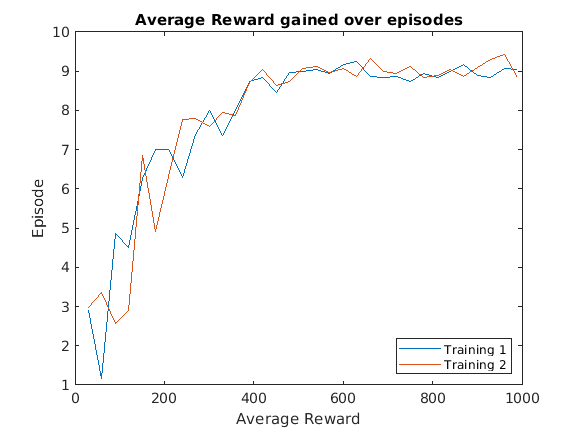

plot(Qlearn1.episodes,Qlearn1.average)
hold on
title('Average Reward gained over episodes')
xlabel('Average Reward') 
ylabel('Episode')
plot(Qlearn2.episodes,Qlearn2.average)
legend({'Training 1','Training 2'},'Location','southeast')
hold off

**Questions**

- Why are the Q-values different for each training process?

- What does the Q-table means?

- What will happen if we initialize the q-table with random values instead of equal values?